It is better to compute gradients using correlation, because it's easier to know which way the derivatives are being computed

im=imread('peppers.png');
filter=[-1,1]

filter =     -1     1


filter=[0 0 0
    -1/2 0 1/2
    0 0 0]

filter =          0         0         0
   -0.5000         0    0.5000
         0         0         0



% Convolution or Correlation matters as this is asymmetric filter

% X filter
disp('X filter');

X filter


filtered_image=imfilter(im,filter,'corr');
disp('Correlation filtered');

Correlation filtered


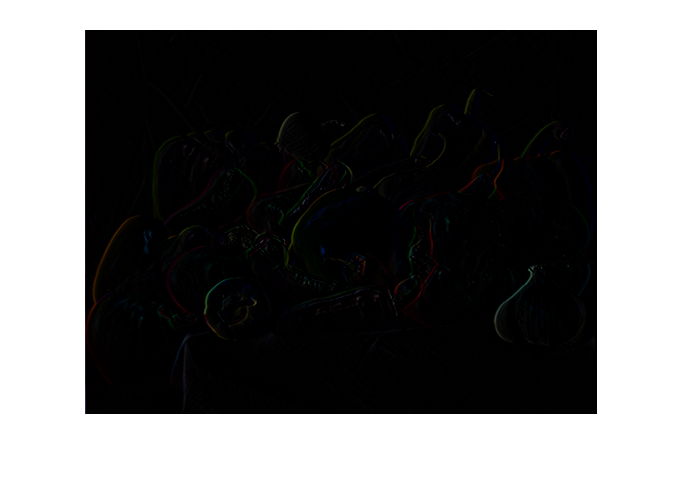

% -1 1 => dark -> bright
imshow(filtered_image)


filtered_image=imfilter(im,filter,'con');
disp('Convolution filtered');

Convolution filtered


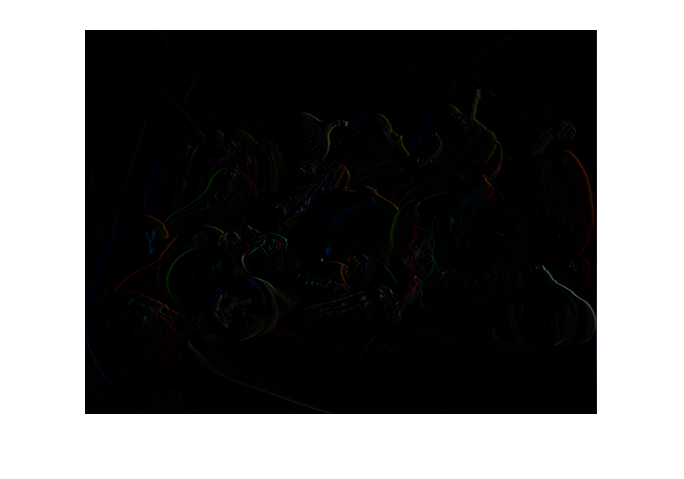

% bright -> dark
imshow(filtered_image)


% Y filter
disp('Y filter');

Y filter


filter=[-1
    1]

filter =     -1
     1


% imfilter by default does correlation
filtered_image=imfilter(im,filter);
disp('Correlation filtered');

Correlation filtered


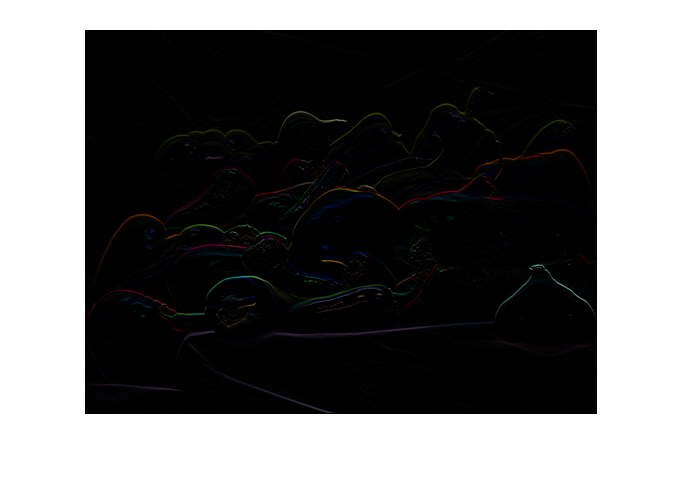

imshow(filtered_image)


filtered_image=imfilter(im,filter,'con');
disp('Convolution filtered');

Convolution filtered


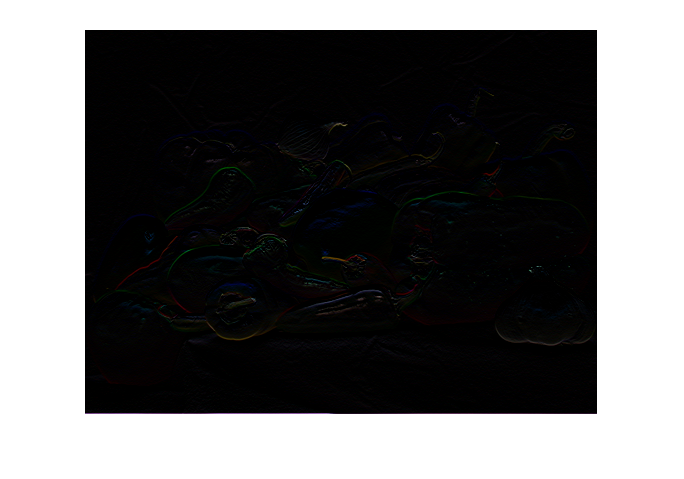

imshow(filtered_image)

Sobel operator

disp('Sobel operators');

Sobel operators


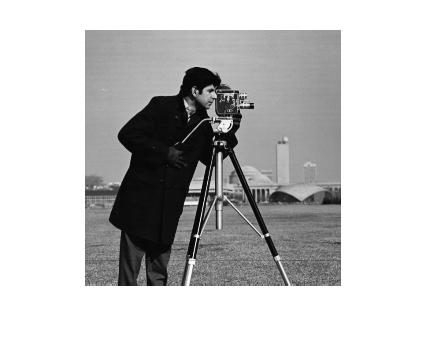

im=imread('cameraman.tif');
imshow(im);

sobel_operator_x=1/8*[-1 0 1
    -2 0 2
    -1 0 1]

sobel_operator_x =    -0.1250         0    0.1250
   -0.2500         0    0.2500
   -0.1250         0    0.1250


sobel_operator_y=1/8*[1 2 1
    0 0 0
    -1 -2 -1]

sobel_operator_y =     0.1250    0.2500    0.1250
         0         0         0
   -0.1250   -0.2500   -0.1250



x_filtered=imfilter(double(im),sobel_operator_x);
y_filtered=imfilter(im,sobel_operator_y);
disp('x-filtered');

x-filtered


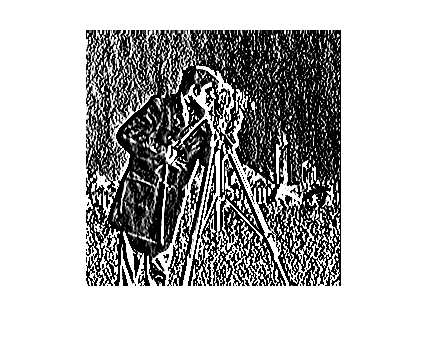

imshow(x_filtered);

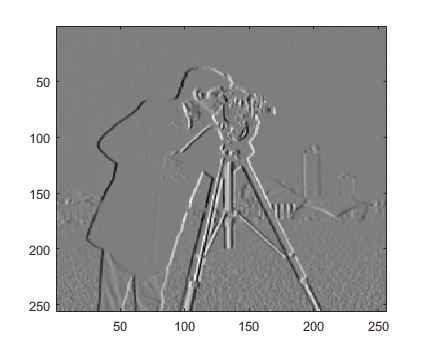

imagesc(x_filtered);

disp('y-filtered');

y-filtered


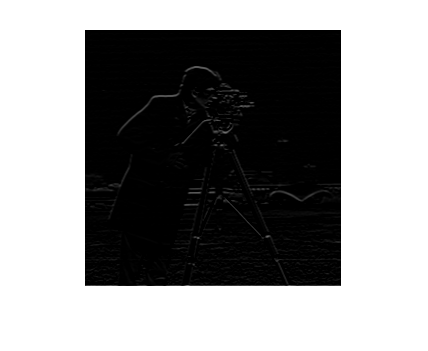

imshow(y_filtered);

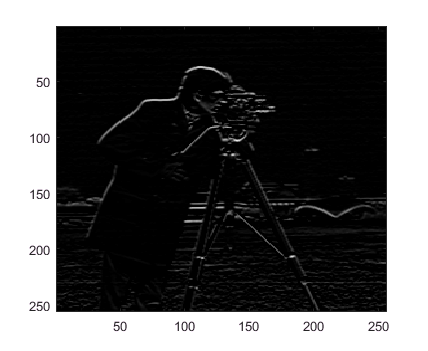

imagesc(y_filtered);


filt=fspecial('sobel')

filt =      1     2     1
     0     0     0
    -1    -2    -1


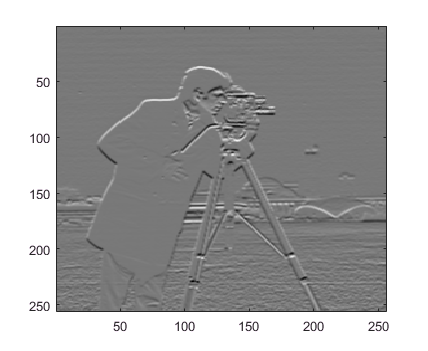

outim=imfilter(double(im),filt);
imagesc(outim);

Gradient direction quiz

Gradients will fail if there is noise in the image

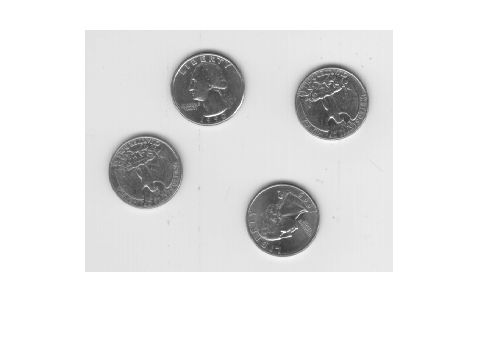

% load and convert iamge to double type, range [0, 1] for convenience
img=double(imread('eight.tif'))/255;
imshow(img);

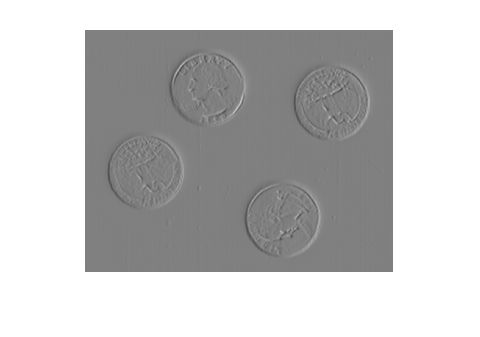


% Compute x, y gradients
[gx gy] = imgradientxy(img,'sobel');
% add 4 and divide by 8 to normalize to range [0,1]
% 1*(-2)+1*(-1)+1*(-1) = -4, 1*2 +1*1+1*1 = 4 -> [-4,4]
% [-4,4]+4=[0,8], [0,8]/8=[0,1]
imshow((gx+4)/8);

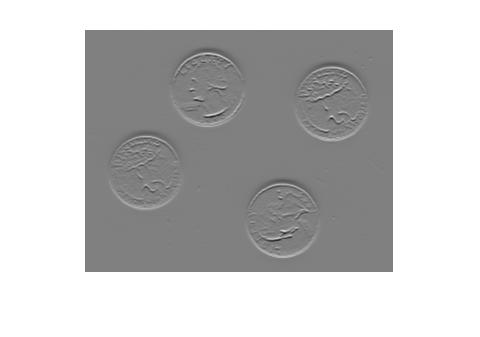

imshow((gy+4)/8);

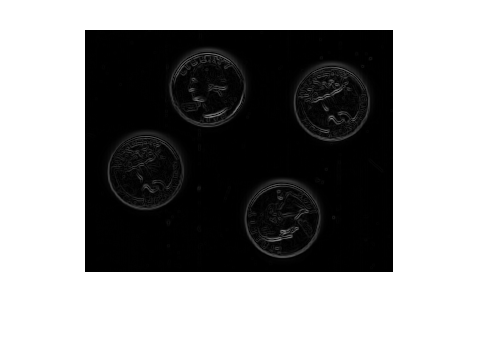


% Obtain gradient magnitude and direction
[gmag gdir] = imgradient(gx,gy);
imshow(gmag/(4*sqrt(2))); % gmag=sqrt(gx^2+gy^2), so: [0,(4*sqrt(2))]

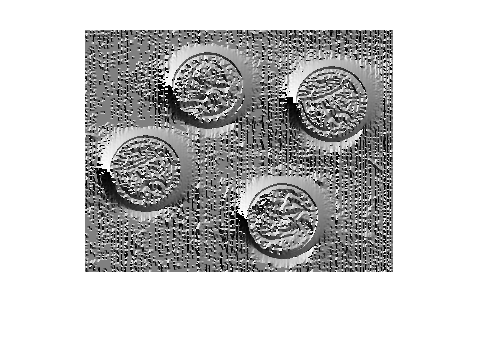

imshow((gdir+180.0)/360.0); %angle in degrees [-180,180]

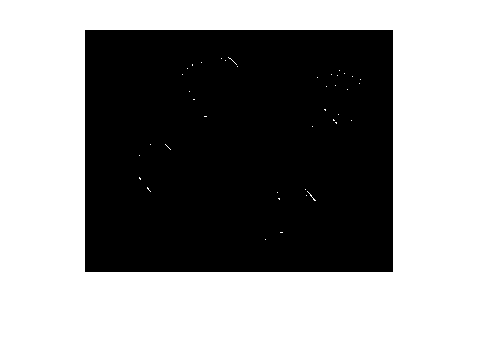


% find gradients with degree from 30 to 60 degrees
my_grad=gmag>=1 & 30<=gdir & gdir <=60; % 45 +/- 15
imshow(my_grad)